clc;clear;
%129-159,174-244这些东西控制

% 打开原文件和新文件
fid_in = fopen('.\\Data\\data_for_doubleAOA_new\\plain_30\\test-30_1.log', 'r');
fid_out = fopen('.\\Data\\data_for_doubleAOA_new\\plain_30\\test-30_1.txt', 'w');

% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

处理完成！


% 读取文本文件
% 读取文本文件
filename = '.\Data\data_for_doubleAOA_new\plain_30\test-30_1.txt';  % <-- 替换为你的实际文件名
fid = fopen(filename, 'r');
if fid == -1  % 新增：文件打开失败检测
    error('文件打开失败，请检查路径或文件名是否正确！');
end
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);

% 获取行内容
lines = rawData{1};

% 初始化CIR存储结构
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前CIR类型（STS0 / STS1）
inside_CIR_block = false;  % 是否处于CIR数据块内

% 遍历每一行，提取CIR数据
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    % 检测CIR类型标志
    if contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待“_________”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待“_________”段 
    end
    
    % 检测“_________”的起始/结束，切换数据块状态
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;
        continue;  % 跳过分隔行
    end
    
    % 若在CIR数据块内，提取I、Q并生成复数
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+),?', 'tokens');  % 兼容末尾逗号
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            
            % 按模式存入对应数组
            if strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出结果验证
disp('=== 提取结果 ===');

=== 提取结果 ===


disp(['STS0 CIR 长度: ', num2str(length(STS0_CIR))]);

STS0 CIR 长度: 75776


disp(['STS1 CIR 长度: ', num2str(length(STS1_CIR))]);

STS1 CIR 长度: 75776


if ~isempty(STS0_CIR)
    disp('STS0 CIR 前5个数据:');
    disp(STS0_CIR(1:min(5, end)));
end

STS0 CIR 前5个数据:


  18.0000 +34.0000i
  79.0000 -36.0000i
   8.0000 + 1.0000i
  26.0000 +88.0000i
  37.0000 +19.0000i



if ~isempty(STS1_CIR)
    disp('STS1 CIR 前5个数据:');
    disp(STS1_CIR(1:min(5, end)));
end

STS1 CIR 前5个数据:


  40.0000 -18.0000i
  59.0000 -23.0000i
  18.0000 -25.0000i
  21.0000 -15.0000i
  75.0000 +10.0000i



% packets_num = length(rxenable_status) ;
packets_num = length(STS0_CIR)/512;
Ipatov_CIR = reshape(Ipatov_CIR(1:1016 * packets_num), 1016, packets_num).';

Index exceeds the number of array elements. Index must not exceed 0.

% Compute the magnitude of the CIR
Ipatov_magnitude = abs(Ipatov_CIR(2,:));

位置 1 处的索引超出数组边界。


% Plot the CIR in the complex plane (real vs imaginary)
figure(10);
plot(Ipatov_magnitude,'b');
title('Magnitude of CIR', 'FontSize', 16);
xlabel('Sample Index', 'FontSize', 14);
ylabel('Magnitude', 'FontSize', 14);
grid on;

[toa, pwr, p_vec, axis] = estimate_ToA_SAMV3(Ipatov_CIR(2,:), 2, 0.1);

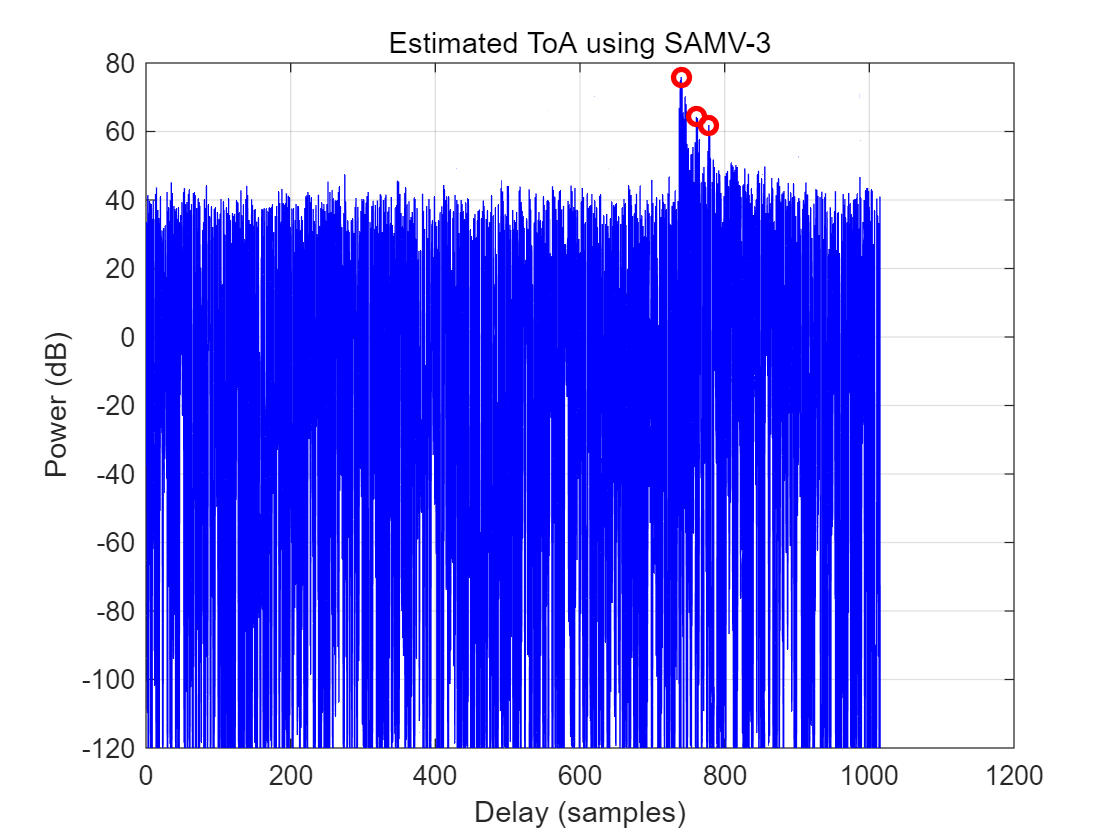


% 可视化
figure;
plot(axis, 10*log10(p_vec + 1e-12), 'b');
hold on;
plot(toa, 10*log10(pwr), 'ro', 'LineWidth', 2);
xlabel('Delay (samples)');
ylabel('Power (dB)');
title('Estimated ToA using SAMV-3');
grid on;

% 2. 参数设置
window_size = 8;              % 滑动平均窗口
lde_thresh = 4;               % 阈值倍数
required_consecutive = 4;     % 需要连续满足的tap数
[fp_index, fp_index_fractional] = LDE_algorithm(Ipatov_CIR(1,:), window_size, lde_thresh, required_consecutive,2);

% 4. 显示结果
fprintf('整数First Path Index: %d\n', fp_index);
fprintf('亚tap精度First Path Index: %.4f\n', fp_index_fractional);

% 共轭转置的问题
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0208;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.26;
%0.26, 0.17

% ==== LUT 数据 ====
% 暂且不用跑
PDOA_LUT_1_CH9 = [...
    -3.3905, -1.5708;
    -3.2998, -1.4661;
    -3.1978, -1.3614;
    -3.0790, -1.2566;
    -2.9326, -1.1519;
    -2.7431, -1.0472;
    -2.5136, -0.9425;
    -2.2552, -0.8378;
    -1.9790, -0.7330;
    -1.6963, -0.6283;
    -1.4002, -0.5236;
    -1.1205, -0.4189;
    -0.8410, -0.3142;
    -0.5628, -0.2094;
    -0.2742, -0.1047;
     0.0000,  0.0000;
     0.2770,  0.1047;
     0.5553,  0.2094;
     0.8339,  0.3142;
     1.1050,  0.4189;
     1.3498,  0.5236;
     1.5912,  0.6283;
     1.8036,  0.7330;
     2.0040,  0.8378;
     2.1975,  0.9425;
     2.3780,  1.0472;
     2.5190,  1.1519;
     2.6505,  1.2566;
     2.7652,  1.3614;
     2.8451,  1.4661;
     2.8932,  1.5708];

% ==== 参数 ====
c = 2.99792458e8;          % 光速 (m/s)
frequency = 7.9872e9;      % 通道9频率 (Hz)
antennaSpacing = 0.0208;   % 天线间距 (m)

% ==== 提取LUT中的PDOA和AoA ====
pdoa_list = PDOA_LUT_1_CH9(:,1);  % LUT中的PDoA值
lut_aoa = PDOA_LUT_1_CH9(:,2);    % LUT中的AoA值

% ==== 理论计算AOA ====
Ln = c / (2 * pi * frequency); % 单位相位差对应的实际距离 (m/rad)
phi = pdoa_list * Ln / antennaSpacing;  % 归一化（无量纲）
phi(phi > 1) = 1; % 归一化超界处理
phi(phi < -1) = -1;
aoa_radian = asin(phi); % 理论计算出的AoA

% ==== 画图 ====
figure;

% 图1：PDoA分布
subplot(2,1,1);
plot(1:length(pdoa_list), pdoa_list, '-o', 'LineWidth', 1.5);
grid on;
title('LUT PDoA Values');
xlabel('LUT Index');
ylabel('PDoA (radian)');

% 图2：LUT AoA vs 理论计算 AoA
subplot(2,1,2);
plot(1:length(lut_aoa), lut_aoa, 'r-o', 'LineWidth', 1.5, 'DisplayName', 'LUT AoA');
hold on;
plot(1:length(aoa_radian), aoa_radian, 'b--x', 'LineWidth', 1.5, 'DisplayName', 'Calculated AoA');
grid on;
legend('show');
title('LUT AoA vs Calculated AoA');
xlabel('LUT Index');
ylabel('AoA (radian)');



pdoa_values_main = [];
degree_values_main = [];


peaks_index_STS0 = [];
peaks_index_STS1 = [];

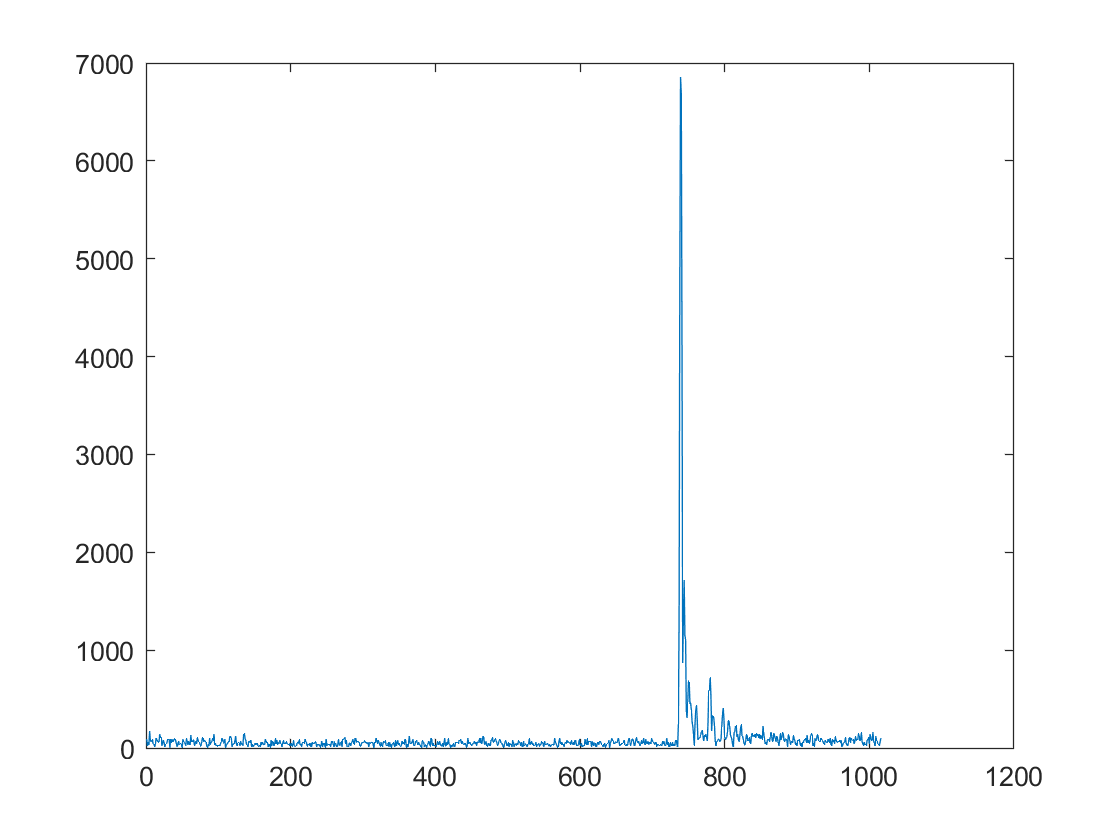

% % 视频初始化
video_filename = '.\Data\TEST\line2.avi';
v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
v.FrameRate = 5;  % 可根据需要调整帧率
open(v);

% 初始化变量

for i = 1:packets_num
    % i =1 ;
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.4;  % 阈值
    min_peak_distance = 3;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index1_STS1 = locs_STS1(1);

    
    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS1];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS0));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    % theta_radians_main = map_pdoa_to_aoa(phase_difference_main);
    theta_degrees_main = rad2deg(theta_radians_main);

    pdoa_values_main(1,end+1) = phase_difference_main;
    degree_values_main(1,end+1) = theta_degrees_main;
    
  

    % % ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布
    plot(abs(Ipatov_CIR(i,:)));
    % 
    % subplot(2,1,1);
    % plot(STS0_magnitude, 'b');
    % hold on;
    % plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    % hold off;
    % title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    % xlabel('Sample Index');
    % ylabel('Magnitude');
    % legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');
    % 
    % subplot(2,1,2);
    % plot(STS1_magnitude, 'r');
    % hold on;
    % plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    % hold off;
    % title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    % xlabel('Sample Index');
    % ylabel('Magnitude');
    % legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');


    % 把当前帧写入视频
    frame = getframe(gcf);
    writeVideo(v, frame);
end



% 关闭视频
close(v);

disp(['视频已保存为: ', video_filename]);

视频已保存为: .\Data\TEST\line2.avi


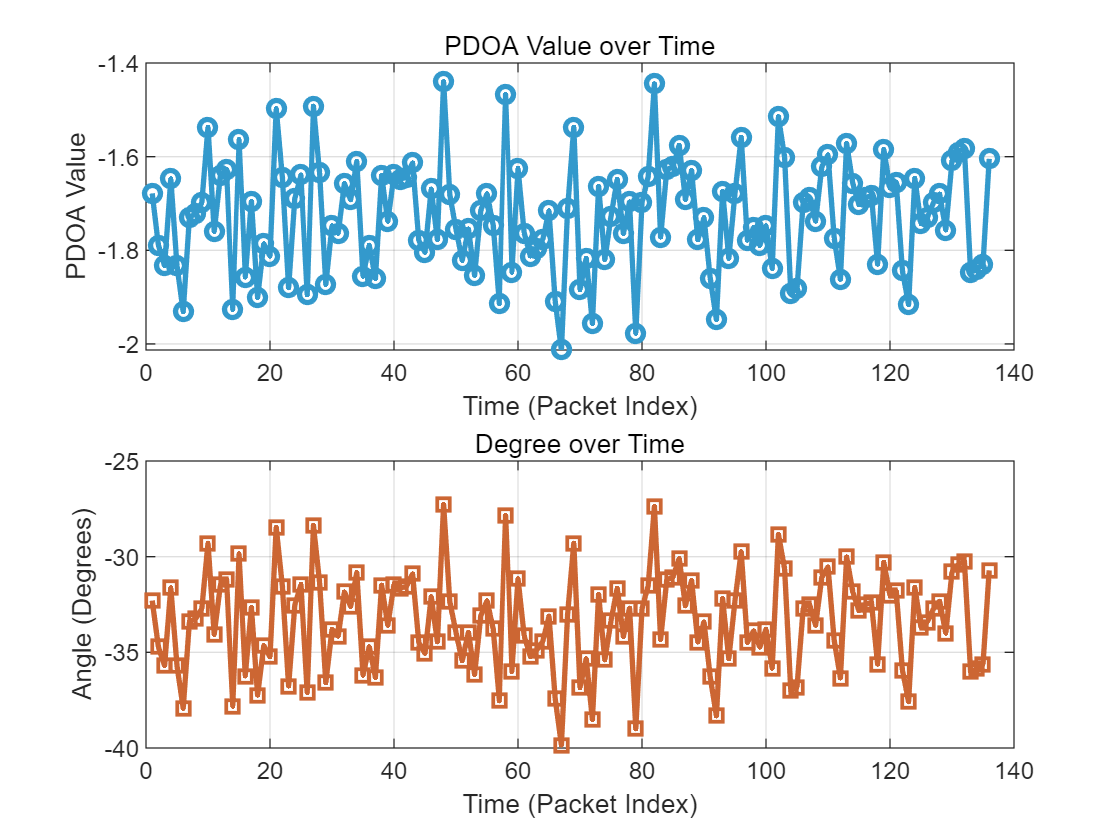

time = 1:length(pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(pdoa_values_main);
mean_degree = mean(degree_values_main);

% 2. 计算标准差
std_pdoa = std(pdoa_values_main);
std_degree = std(degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.15


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 0.14



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -2.68


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 2.64


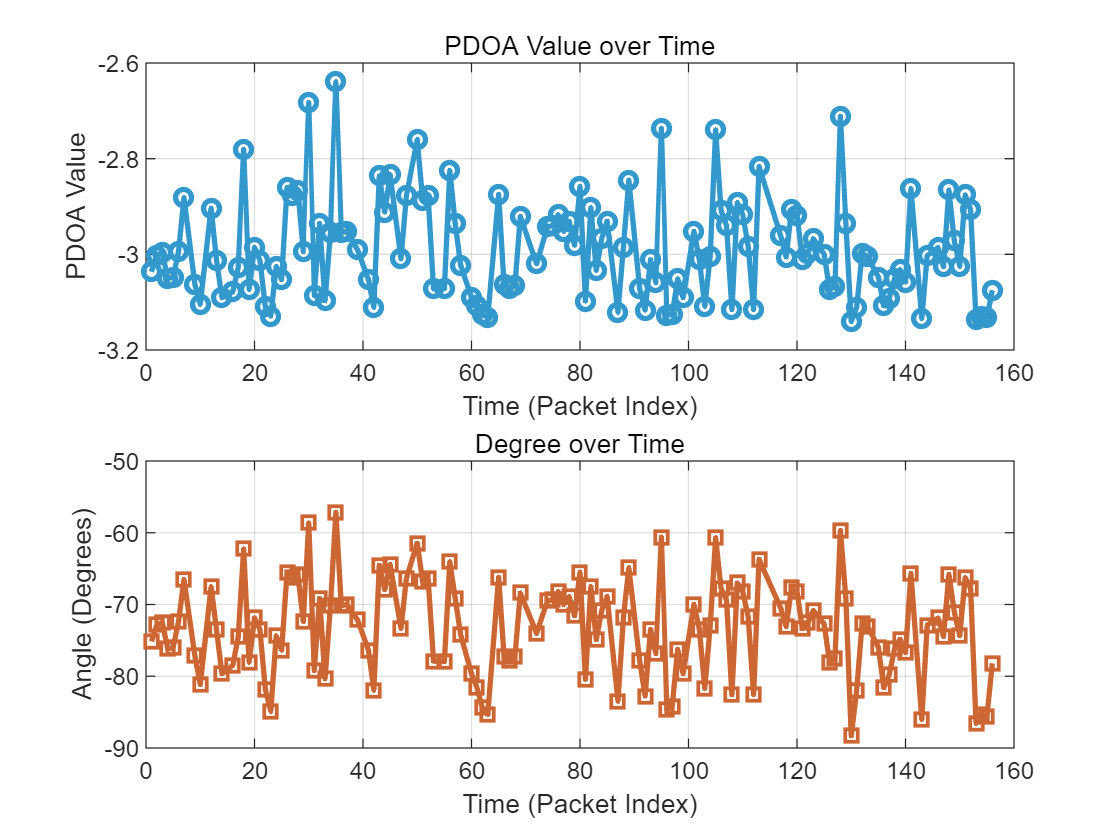

% 原始时间向量
time = 1:length(pdoa_values_main);

% 使用已有的均值和标准差
% mean_pdoa, std_pdoa
% mean_degree, std_degree

% 设置过滤阈值（通常为2或3倍标准差）
threshold = 2;

% 筛选非异常值的逻辑索引
valid_idx = abs(pdoa_values_main - mean_pdoa) <= threshold * std_pdoa & ...
            abs(degree_values_main - mean_degree) <= threshold * std_degree;

% 应用筛选条件
filtered_pdoa = pdoa_values_main(valid_idx);
filtered_degree = degree_values_main(valid_idx);
filtered_time = time(valid_idx);

% 绘图：滤除异常值后的数据
figure;
subplot(2,1,1);
plot(filtered_time, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(filtered_time, filtered_degree, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 再次计算滤波后数据的统计量
mean_filtered_pdoa = mean(filtered_pdoa);
std_filtered_pdoa = std(filtered_pdoa);
mean_filtered_degree = mean(filtered_degree);
std_filtered_degree = std(filtered_degree);

% 输出滤除异常值后的结果
fprintf('【滤除异常值后的结果】\n');

【滤除异常值后的结果】


fprintf('PDOA 平均值: %.2f\n', mean_filtered_pdoa);

PDOA 平均值: -2.99


fprintf('PDOA 标准差: %.2f\n', std_filtered_pdoa);

PDOA 标准差: 0.11



fprintf('\nDegree 平均值: %.2f\n', mean_filtered_degree);


Degree 平均值: -73.29


fprintf('Degree 标准差: %.2f\n', std_filtered_degree);

Degree 标准差: 6.65


AOA = -50;
AOA = deg2rad(AOA);
PDOA_GT = antennaSpacing * sin(AOA) * (2 * pi) / lambda

reflection_angel = rad2deg(atan(1.9/3.2))

% function x0 = findLocalization(theta1, theta2, phi1, phi2, rTOF)
%     theta1 = deg2rad(theta1);
%     theta2 = deg2rad(theta2);
%     phi1 = deg2rad(phi1);
%     phi2 = deg2rad(phi2);
% 
%     % 定义网格大小和范围
%     gridRange = 20;
%     gridSize = 0.5;
% 
%     % 生成网格点坐标
%     [x1, y1, x2, y2] = ndgrid(-gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange, -gridRange:gridSize:gridRange);
%     x0 = [x1(:), y1(:), x2(:), y2(:)];
% 
%     % 计算目标函数值
%     objectiveValues = objectiveFunction(x0, theta1, theta2, phi1, phi2, rTOF);
% 
%     % 找到最小值
%     [~, idx] = min(objectiveValues);
%     x0 = x0(idx, :);
% end
% 
% function fval = objectiveFunction(x, theta1, theta2, phi1, phi2, rTOF)
%     x1 = x(:, 1);
%     y1 = x(:, 2);
%     x2 = x(:, 3);
%     y2 = x(:, 4);
% 
%     % 计算目标函数值
%     fval = (tan(theta1) - x1./y1).^2 + (tan(theta2) - x2./y2).^2 + (tan(phi1 + theta1 - phi2) - (x1 - x2)./(y1 - y2)).^2 + ((rTOF * physconst('Lightspeed') * 1e-9) - (-sqrt(x1.^2 + y1.^2) + sqrt(x2.^2 + y2.^2) + sqrt((x1 - x2).^2 + (y1 - y2).^2))).^2;
% end
% 
% function xOpt = optimizeLocalization(x0, theta1, theta2, phi1, phi2, rTOF)
%     % 转换角度为弧度
%     theta1 = deg2rad(theta1);
%     theta2 = deg2rad(theta2);
%     phi1 = deg2rad(phi1);
%     phi2 = deg2rad(phi2);
% 
%     % 迭代搜索参数
%     searchParams = {
%         struct('range', 1, 'step', 0.03) % 中等搜索范围和步长
%     };
% 
%     % 逐级迭代搜索
%     for i = 1:length(searchParams)
%         param = searchParams{i};
%         fineRange = param.range;
%         fineStep = param.step;
% 
%         % 动态生成精细的网格点坐标
%         x1Range = (x0(1)-fineRange):fineStep:(x0(1)+fineRange);
%         y1Range = (x0(2)-fineRange):fineStep:(x0(2)+fineRange);
%         x2Range = (x0(3)-fineRange):fineStep:(x0(3)+fineRange);
%         y2Range = (x0(4)-fineRange):fineStep:(x0(4)+fineRange);
% 
%         [X1, Y1, X2, Y2] = ndgrid(x1Range, y1Range, x2Range, y2Range);
%         fineGrid = [X1(:), Y1(:), X2(:), Y2(:)];
% 
%         % 计算目标函数值
%         fineObjectiveValues = objectiveFunction(fineGrid, theta1, theta2, phi1, phi2, rTOF);
% 
%         % 找到最小值
%         [~, fineIdx] = min(fineObjectiveValues);
%         x0 = fineGrid(fineIdx, :);
%         % disp(['Iteration ', num2str(i), ' Best x0: ', mat2str(x0)]);
%     end
% 
%     xOpt = x0;
% end



% 接收端法线右侧正方向，发射端法线左侧正方向
x0=findLocalization(45,-23,45,-23,8)
x0=optimizeLocalization(x0,45,-23,45,-23,8)

% 将x0整理成2行2列
x0 = reshape(x0, 2, 2);

% 翻转坐标（根据需要修正方向）
x0(1,:) = -x0(1,:); % 翻转x轴
x0(2,:) = -x0(2,:); % 翻转y轴

% 定义旋转矩阵（顺时针45度）
theta = deg2rad(45);
R = [cos(theta), sin(theta); -sin(theta), cos(theta)];

% 旋转每个点
rotated_vector = R * x0; 


% 显示最终结果
disp('定位结果（第一列是标签，第二列是反射物）：');
disp(rotated_vector);

clc;
clear;
close all;

 % % 绘制信号
    % figure;
    % plot(STS0_magnitude,'k', 'LineWidth', 3);  % 黑色线条，可根据需要修改颜色
    % axis off                          % 关闭坐标轴
    % set(gca, 'Color', 'none');        % 坐标区背景也设为透明
    % 
    % % 调整边距
    % set(gca, 'position', [0 0 1 1]);  % 图像占满整个画布
    % set(gcf, 'Units', 'pixels', 'Position', [100 100 800 200]);  % 可设置图像分辨率大小
    % 
    % % 保存为透明背景图像（推荐PNG格式）
    % exportgraphics(gca, 'STS0.png', 'BackgroundColor', 'none', 'Resolution', 300);

%探究相对飞行时间的准确性 
interval1 = peaks_index_STS1(:,2) - peaks_index_STS1(:,1);
error1 = interval1 * c * 1e-9 - 2.5231;

interval2 = peaks_index_STS0(:,2) - peaks_index_STS0(:,1);
error2 = interval2 * c * 1e-9 - 2.5231;

error = [error1;error2]

% 添加微小扰动（标准差为1e-4米）
jitter = 15 * randn(size(error)) * 1e-2;  % 正态分布扰动
error_jittered = error + jitter;

% 绘制误差CDF图
figure;
cdfplot(abs(error_jittered));  % 绘制CDF
xlabel('相对飞行距离误差 (m)');
ylabel('CDF');
title('');
grid on;
hold on;

% 计算中位误差
median_error = median(abs(error_jittered));



% 为手动绘制中位误差点的横线与竖线做准备
% 计算CDF数据（以便获取纵坐标）
[sorted_errors, sort_idx] = sort(abs(error_jittered));
cdf = (1:length(sorted_errors))' / length(sorted_errors);

% 找到最接近中位误差的位置
[~, idx_median] = min(abs(sorted_errors - median_error));
x_median = sorted_errors(idx_median);
y_median = cdf(idx_median);

% 绘制从坐标轴到中位误差点的辅助虚线
plot([x_median, x_median], [0, y_median], 'r--', 'LineWidth', 1.2);  % 竖线
plot([0, x_median], [y_median, y_median], 'r--', 'LineWidth', 1.2);  % 横线

% 标注中位误差点
plot(x_median, y_median, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
text(x_median + 0.02, y_median + 0.02, ...
    sprintf('中位误差 = %.3f m', x_median), ...
    'Color', 'r', 'FontSize', 10);

% 保持图像风格一致
box on;

% 探究不同环境
%=========================% 
% 真实参数（无噪声）讨论间
true_theta1 = 45;    % AoA 1
true_theta2 = 4.9;   % AoA 2 
true_phi1   = 45;    % AoD 1 
true_phi2   = 4.9;   % A0D 2 
true_rTOF   = 6;     % 飞行时间（ns） 
orientation = 45;    %接收天线朝向
true_tag_pos = [3.2 ; 0]; % 第一列是标签位置 

% true_theta1 = 45;    % 发射端角度 
% true_theta2 = -5;   % 接收端角度 
% true_phi1   = 45;    % 法线夹角 
% true_phi2   = -5;   % 法线夹角 
% true_rTOF   = 12;     % 飞行时间（ns）
% orientation = 45;    %接收天线朝向

true_tag_pos = findLocalization(true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = optimizeLocalization(true_tag_pos, true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = reshape(true_tag_pos, 2, 2); 
true_tag_pos(1,:) = -true_tag_pos(1,:); 
true_tag_pos(2,:) = -true_tag_pos(2,:); 

theta = deg2rad(45); 
R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
true_tag_pos = R * true_tag_pos; 

% true_tag_pos = true_tag_pos(:,1); % 第一列是标签位置 


%=========================% 
% 模拟误差大小 
angle_error_deg = 0;    % 角度误差 ±5度 
distance_error_m = 0; % 距离误差 ±0.3米 

%=========================% 
% 仿真次数（为了稳健，可以多次仿真） 
num_trials = 1; 

%=========================% 
% 记录误差 
position_errors = zeros(num_trials, 1); 

% 记录超过1m误差时的角度和距离
error_angles_distances = [];

for trial = 1:num_trials

    noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg); 
    noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg); 
    noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg); 
    noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg); 

    lightspeed = physconst('Lightspeed'); % m/s 
    true_distance = true_rTOF * lightspeed * 1e-9; % ns -> m 
    noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m); % 加测量误差 
    noisy_rTOF = noisy_distance / lightspeed / 1e-9; % 再换回ns 

    x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
    x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 

    x0 = reshape(x0, 2, 2); 
    x0(1,:) = -x0(1,:); 
    x0(2,:) = -x0(2,:); 

    theta = deg2rad(45); 
    R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
    rotated_vector = R * x0; 

    estimated_tag_pos = rotated_vector(:,1); % 第一列是标签位置 

    error_val = norm(estimated_tag_pos - true_tag_pos); 
    position_errors(trial) = error_val;

    if error_val > 1
        error_angles_distances = [error_angles_distances; ...
            trial, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_distance];
    end

end

% 显示结果
disp('误差超过1米的情况：');
disp('Trial   theta1   theta2   phi1   phi2   distance(m)');
disp(error_angles_distances);



mean_error = mean(position_errors);
std_error = std(position_errors);

fprintf('模拟次数: %d 次\n', num_trials);
fprintf('角度误差: ±%.1f°，距离误差: ±%.2f m\n', angle_error_deg, distance_error_m);
fprintf('平均定位误差: %.4f m\n', mean_error);
fprintf('定位误差标准差: %.4f m\n', std_error);


figure;
histogram(position_errors, 'BinWidth', 0.05);
xlabel('定位误差 (米)');
ylabel('次数');
title(sprintf('角度误差±%.1f° + 距离误差±%.2fm\n平均误差 %.3fm', angle_error_deg, distance_error_m, mean_error));
grid on;

% 绘制CDF图并标出中位误差位置
figure;
sorted_errors = sort(position_errors);
cdf = (1:num_trials) / num_trials;
plot(sorted_errors, cdf, 'LineWidth', 2);
hold on;

% 计算中位误差
median_error = median(position_errors);

% 找到中位误差对应的纵坐标 (大约是0.5) 和最近的点
[~, idx_median] = min(abs(sorted_errors - median_error));
x_median = sorted_errors(idx_median);
y_median = cdf(idx_median);

% 手动画短横线和竖线（仅到点为止）
plot([x_median, x_median], [0, y_median], '--r', 'LineWidth', 1.5); % 竖线
plot([0, x_median], [y_median, y_median], '--r', 'LineWidth', 1.5); % 横线

% 添加标注
text(x_median + 0.02, y_median + 0.02, sprintf('中位误差 = %.3f m', x_median), 'Color', 'r');

xlabel('定位误差 (米)');
ylabel('CDF');
grid on;

% 探究距离影响

%=========================% 
% 固定参数：角度与误差
true_theta1 = 45;
true_theta2 = -23;
true_phi1   = 45;
true_phi2   = -23;
orientation = 45;

angle_error_deg = 4;        % 角度误差 ±6度
distance_error_m = 0.3;    % 距离误差 ±0.35m
num_trials = 10;           % 每个距离的仿真次数

%=========================% 
% 距离设置（单位：米）
distances_m = 1:1:10;       % 1米到10米，每步1米
num_distances = length(distances_m);

% 结果记录
mean_errors = zeros(num_distances, 1);
std_errors = zeros(num_distances, 1);

for d_idx = 1:num_distances
    true_distance = distances_m(d_idx);
    true_rTOF = true_distance / physconst('Lightspeed') / 1e-9; % ns

    true_tag_pos = findLocalization(true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
    true_tag_pos = optimizeLocalization(true_tag_pos, true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
    true_tag_pos = reshape(true_tag_pos, 2, 2); 
    true_tag_pos(1,:) = -true_tag_pos(1,:); 
    true_tag_pos(2,:) = -true_tag_pos(2,:); 

    theta = deg2rad(orientation); 
    R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
    true_tag_pos = R * true_tag_pos; 
    true_tag_pos = true_tag_pos(:,1); 

    position_errors = zeros(num_trials, 1); 

    for trial = 1:num_trials
        noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg); 
        noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg); 
        noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg); 
        noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg); 

        noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m); 
        noisy_rTOF = noisy_distance / physconst('Lightspeed') / 1e-9; 

        x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
        x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 

        x0 = reshape(x0, 2, 2); 
        x0(1,:) = -x0(1,:); 
        x0(2,:) = -x0(2,:); 
        rotated_vector = R * x0; 
        estimated_tag_pos = rotated_vector(:,1); 

        error_val = norm(estimated_tag_pos - true_tag_pos); 
        position_errors(trial) = error_val;
    end

    mean_errors(d_idx) = mean(position_errors);
    std_errors(d_idx) = std(position_errors);
end

%=========================% 
% 绘图：平均误差和标准差随距离变化
figure;
errorbar(distances_m, mean_errors, std_errors, 'o-', 'LineWidth', 2);
xlabel('真实距离 (米)');
ylabel('定位误差 (米)');
grid on;
legend('平均误差 ±1σ');


% 探究发包数量对定位结果的影响
%=========================% 
% ==================== 固定参数 ====================
true_theta1 = 45;
true_theta2 = -23;
true_phi1   = 45;
true_phi2   = -23;
orientation = 45;
true_rTOF = 12; % ns
lightspeed = physconst('Lightspeed'); % m/s 
true_distance = true_rTOF * lightspeed * 1e-9; % ns -> m 
true_tag_pos = findLocalization(true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = optimizeLocalization(true_tag_pos, true_theta1,true_theta2,true_phi1,true_phi2,true_rTOF);
true_tag_pos = reshape(true_tag_pos, 2, 2);
true_tag_pos(1,:) = -true_tag_pos(1,:);
true_tag_pos(2,:) = -true_tag_pos(2,:);
R = [cosd(orientation), sind(orientation); -sind(orientation), cosd(orientation)];
true_tag_pos = R * true_tag_pos;
true_tag_pos = true_tag_pos(:,1);


angle_error_deg = 5;         % 角度误差 ±5度
distance_error_m = 0.3;      % 距离误差 ±0.3m

% ==================== 发包设置 ====================
trial_counts = [5, 10, 20, 50];           % 每组发包数
fixed_trial_number = 50;               % 每种发包设置的重复次数
num_trial_settings = length(trial_counts);
errors_all_trials = cell(1, num_trial_settings);  % 每种设置下误差集

% ==================== 主循环 ====================
for t_idx = 1:num_trial_settings
    num_packets = trial_counts(t_idx);                     % 每组发包次数
    averaged_errors = zeros(fixed_trial_number, 1);        % 每组取平均的误差

    for group = 1:fixed_trial_number
        error_per_group = zeros(num_packets, 1);           % 单组内多个误差

        for pkt = 1:num_packets
            % 添加噪声
            noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg);
            noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m);
            noisy_rTOF = noisy_distance / physconst('Lightspeed') / 1e-9;

            % 定位
            x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF);
            x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF);
            x0 = reshape(x0, 2, 2);
            x0(1,:) = -x0(1,:);
            x0(2,:) = -x0(2,:);
            estimated_tag_pos = R * x0;
            estimated_tag_pos = estimated_tag_pos(:,1);

            % 单次误差
            error_per_group(pkt) = norm(estimated_tag_pos - true_tag_pos);
        end

        % 每组取平均误差
        averaged_errors(group) = mean(error_per_group);
    end

    % 存入结果
    errors_all_trials{t_idx} = averaged_errors;
end



figure;
hold on;
colors = lines(num_trial_settings); % 使用默认颜色方案

h = gobjects(num_trial_settings,1); % 用于存储每条主曲线句柄

for t_idx = 1:num_trial_settings
    data = errors_all_trials{t_idx};

    % 绘制 CDF 曲线
    h(t_idx) = cdfplot(data);
    set(h(t_idx), 'LineWidth', 2, 'Color', colors(t_idx,:));

    % 计算中位误差
    med_err = median(data);

    % 获取 CDF 点
    [f, x] = ecdf(data);
    [~, idx] = min(abs(x - med_err));
    y_median = f(idx);

    % 添加中位误差虚线（不加入 legend）
    plot([med_err, med_err], [0, y_median], '--', 'Color', colors(t_idx,:), 'LineWidth', 1.2, 'HandleVisibility','off');
end

legend(h, {'20 packets', '50 packets', '10 packets', '5 packets'}, 'Location', 'southeast');

xlabel('定位误差（m）', 'FontSize', 14);
ylabel('CDF', 'FontSize', 14);
% title('经验 CDF（含中位误差）', 'FontSize', 14);
grid on;





%=========================% 
% 坐标设置
anchor_pos = [0; 0];          % 锚点位置
tag_pos = [1.6; 0];           % 标签真实位置
reflector_pos = [0.8; 2.0];   % 反射物体位置

%=========================% 
% 模拟误差设置 
angle_error_deg = 5;        % 角度误差 ±5°
distance_error_m = 0.3;     % 距离误差 ±0.3m
num_trials = 100;           % 仿真次数 

position_errors = zeros(num_trials, 1);
error_angles_distances = [];

lightspeed = physconst('Lightspeed'); % m/s

%=========================% 
% 计算真实参数
% 直射路径向量
vec_direct = tag_pos - anchor_pos;
true_theta1 = atan2d(vec_direct(2), vec_direct(1)); % AOD
true_theta2 = atan2d(-vec_direct(2), -vec_direct(1)); % AOA
true_rTOF_direct = norm(vec_direct) / lightspeed / 1e-9; % ns

% 反射路径：tag -> reflector -> anchor
vec_tag2reflector = reflector_pos - tag_pos;
vec_reflector2anchor = anchor_pos - reflector_pos;
true_phi1 = atan2d(vec_tag2reflector(2), vec_tag2reflector(1)); % tag入射角
true_phi2 = atan2d(vec_reflector2anchor(2), vec_reflector2anchor(1)); % anchor出射角
true_rTOF_reflect = (norm(vec_tag2reflector) + norm(vec_reflector2anchor)) / lightspeed / 1e-9; % ns

% %=========================% 
% for trial = 1:num_trials
% 
%     % 添加角度误差
%     noisy_theta1 = true_theta1 + (rand * 2 * angle_error_deg - angle_error_deg); 
%     noisy_theta2 = true_theta2 + (rand * 2 * angle_error_deg - angle_error_deg); 
%     noisy_phi1   = true_phi1   + (rand * 2 * angle_error_deg - angle_error_deg); 
%     noisy_phi2   = true_phi2   + (rand * 2 * angle_error_deg - angle_error_deg); 
% 
%     % 添加距离误差
%     true_distance = true_rTOF_reflect * lightspeed * 1e-9; 
%     noisy_distance = true_distance + (rand * 2 * distance_error_m - distance_error_m); 
%     noisy_rTOF = noisy_distance / lightspeed / 1e-9;
% 
%     % 调用定位函数
%     x0 = findLocalization(noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
%     x0 = optimizeLocalization(x0, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_rTOF); 
% 
%     x0 = reshape(x0, 2, 2); 
%     x0(1,:) = -x0(1,:); 
%     x0(2,:) = -x0(2,:); 
% 
%     % 旋转对齐
%     theta = deg2rad(45); 
%     R = [cos(theta), sin(theta); -sin(theta), cos(theta)]; 
%     rotated_vector = R * x0; 
%     estimated_tag_pos = rotated_vector(:,1); 
% 
%     % 计算误差
%     error_val = norm(estimated_tag_pos - tag_pos); 
%     position_errors(trial) = error_val;
% 
%     if error_val > 1
%         error_angles_distances = [error_angles_distances; ...
%             trial, noisy_theta1, noisy_theta2, noisy_phi1, noisy_phi2, noisy_distance];
%     end
% end
% 
% %=========================% 
% % 显示统计结果
% disp('误差超过1米的情况：');
% disp('Trial   theta1   theta2   phi1   phi2   distance(m)');
% disp(error_angles_distances);
% 
% mean_error = mean(position_errors);
% std_error = std(position_errors);
% 
% fprintf('模拟次数: %d 次\n', num_trials);
% fprintf('角度误差: ±%.1f°，距离误差: ±%.2f m\n', angle_error_deg, distance_error_m);
% fprintf('平均定位误差: %.4f m\n', mean_error);
% fprintf('定位误差标准差: %.4f m\n', std_error);
% 
% %=========================% 
% % 绘图
% figure;
% histogram(position_errors, 'BinWidth', 0.05);
% xlabel('定位误差 (米)');
% ylabel('次数');
% title(sprintf('角度误差±%.1f° + 距离误差±%.2fm\n平均误差 %.3fm', angle_error_deg, distance_error_m, mean_error));
% grid on;


1.6* sqrt(2)

figure(100);
% 发射点、接收点
plot(0, 0, 'ro'); % 发射端
plot(12, 0, 'bo'); % 接收端

% 发射方向线（以角度 -5° 和 -3°）
quiver(0, 0, cosd(-5), sind(-5), 'r');
quiver(0, 0, cosd(-3), sind(-3), 'r--');

% 接收方向线
quiver(12, 0, -cosd(-5), -sind(-5), 'b');
quiver(12, 0, -cosd(-3), -sind(-3), 'b--');

legend('Tx', 'Rx', '-5°', '-3°');
title('方向偏差带来的交点偏移');


sqrt(1.9*1.9+0.3*0.3)